## **DCT Evolution**

### 1.1 Importing data

Import data from an audiofile which is the concatenation of every 8s close miked sample from 1-127 midi velocity, with all velocity layers loaded, and all hit variation features turned off. 

fs=44100

fs = 44100

load DuplicatedSamplesA.mat;
load DuplicatedSamplesB.mat;
load DuplicatedSamplesC.mat;
load DuplicatedSamplesD.mat;
load DuplicatedSamplesE.mat;
load DuplicatedSamplesF.mat;
load DuplicatedSamplesG.mat;

DuplicatedSamples=[DuplicatedSamplesA,DuplicatedSamplesB,DuplicatedSamplesC,DuplicatedSamplesD,DuplicatedSamplesE,DuplicatedSamplesF,DuplicatedSamplesG];


%Find unique drum samples based on the first 10 samples of each recording.
%(Here there are 67 unique drum samples, mapped to 127 velocities.) 
C=DuplicatedSamples(1:10,:)';
[A,ia,ic] = unique(C, 'rows', 'first');
UniqueVelocities=sort(ia); 
UniqueSamples=DuplicatedSamples(:,sort(ia));
text = [num2str(length(UniqueVelocities)),' unique drum samples found'];
disp(text);

67 unique drum samples found



%Remove anomalous drum sample (off-center)
UniqueSamples(:,3)=[];
UniqueVelocities(3)=[];
text = [num2str(length(UniqueVelocities)),' samples deemed to be non-anomalous'];
disp(text);

66 samples deemed to be non-anomalous


### 1.2 Mapping midi velocity to LUFS

Midi velocity is a useful symbolic notation, but it is limited as an independent variable. It is discrete, it has no absolute meaning, and samples of identical volume would be mapped to multiple neighbouring velocities, because of how velocity layers are programmed. Integrated loudness will instead be used as the independent variable in this study. This graph shows the mapping between the two quantities. 

%Calculate integrated loudness
for i=1:numel(UniqueVelocities)
    loudness = integratedLoudness(UniqueSamples(:,i),fs);
    Loudness(:,i)=loudness;
end

%Plot graph
scatter(UniqueVelocities,Loudness)
LoudFit=fit(UniqueVelocities,Loudness','exp2')

LoudFit =      General model Exp2:
     LoudFit(x) = a*exp(b*x) + c*exp(d*x)
     Coefficients (with 95% confidence bounds):
       a =      -5.532  (-7.525, -3.54)
       b =    -0.08494  (-0.1477, -0.0222)
       c =      -48.69  (-50.52, -46.85)
       d =   -0.007165  (-0.007592, -0.006737)

BestFitLoud=LoudFit(UniqueVelocities')

BestFitLoud =   -53.4205
  -51.9388
  -49.9610
  -49.3575
  -48.7783
  -47.6861
  -47.1699
  -46.6717
  -46.1902
  -45.2727


hold on
plot(UniqueVelocities,BestFitLoud,'--r')
x0=10;
y0=10;
width=1150;
height=700

height = 700

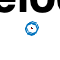

set(gcf,'position',[x0,y0,width,height])
box(gca,'on');
set(gca,'FontSize',20);
xlabel('Midi Velocity')
ylabel('Integrated Loudness (LUFS)')
title('Mapping midi velocity to loudness')

### 1.3 DCT Representation

This figure shows the DCT representation of the fundamental frequency of a sample, along with it's envelope and instantaneous phase, from the Hilbert transform.

%Set frequency resolution
Scaling=1;
N=Scaling*(8*fs);   %Length of DCT (Scale up to increase frequency resolution)
FrequencyResolution=fs/N;   
FX=[1:N]*FrequencyResolution/2;%Create Frequency axis vector

%Calculate DCT of each sample
DCT=[];
for i=1:size(UniqueSamples,2)
    DCT(:,i)=((dct(UniqueSamples(:,i),N)));
end

%Calculate Amplitude function via Hilbert Transform
AmplitudeFunction=abs(hilbert((DCT)));

%Calculate Phase function via Hilbert Transform
WrappedPhaseFunction=(angle(hilbert(DCT)));

%Estimate fundamental frequencies and average
[~,FundamentalIndex]=max(DCT);
Fundamentals=FX(FundamentalIndex);
AvgFundamental=mode(Fundamentals);

%Estimate frequency limits of modal feature
%FrequencyLimits=[AvgFundamental-10 AvgFundamental+50];
FrequencyLimits=[AvgFundamental-55 AvgFundamental+55];
IndexLimits=FrequencyLimits*2*8;

%Begin to extract feautures of fundamental mode
X=repmat(FX(IndexLimits(1):IndexLimits(2))',1,length(UniqueVelocities));
Ycrop=AmplitudeFunction(IndexLimits(1):IndexLimits(2),:);

%Frequency axis alignment to compensate for slight tuning variations 
% (based on peak gradient of amplitude function)
[~,idx2]=max(diff(Ycrop));
ShiftCorrection=mode(idx2)-idx2

ShiftCorrection =      2     2     2     3     3     3     3     3     2     2     2     2     1     1     0     1     1     1     0     0     0     0     0     0     0    -1     1     3    -1     2     0     0    -1     5    -1     3     1     0     7     8     9    10    12    12     8    10     7     9   -36   -21


AmplitudeFunctionS=[];
for i=1:numel(UniqueVelocities)
DCTshift(:,i)=circshift(DCT(:,i),ShiftCorrection(i));
AmplitudeFunctionShift(:,i)=circshift(AmplitudeFunction(:,i),ShiftCorrection(i));
WrappedPhaseFunctionShift(:,i)=circshift(WrappedPhaseFunction(:,i),ShiftCorrection(i));
end

%Extract aligned features
Ydct=DCTshift(IndexLimits(1):IndexLimits(2),:);
Yamp=AmplitudeFunctionShift(IndexLimits(1):IndexLimits(2),:);
Yphase=flipud(unwrap(flipud(WrappedPhaseFunctionShift(IndexLimits(1):IndexLimits(2),:))));

%Choose Sample
j=49

j = 49


%Plot graphs
ax1=subplot(3,1,1)

ax1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.7093 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


plot(X(:,j),Ydct(:,j),'lineWidth',2)
title('DCT representation of fundamental')
x0=10;
y0=10;
width=1150;
height=700

height = 700

set(gcf,'position',[x0,y0,width,height])
% ylim(axes1,[-17.4191352493244 19.6795712708698]);
box(gca,'on');
% Set the remaining axes properties
set(gca,'FontSize',20);
ylabel('DCT Magnitude')

ax2=subplot(3,1,2)

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


plot(X(:,j),Yamp(:,j),'lineWidth',2)
title('Amplitude function')
x0=10;
y0=10;
width=1150;
height=700

height = 700

set(gcf,'position',[x0,y0,width,height])
box(gca,'on');
set(gca,'FontSize',20);
ylabel('DCT Magnitude')

ax3=subplot(3,1,3)

ax3 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


plot(X(:,j),Yphase(:,j),'lineWidth',2)
title('Phase function')
linkaxes([ax1,ax2,ax3],'x');
x0=10;
y0=10;
width=1150;
height=700

height = 700

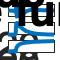

set(gcf,'position',[x0,y0,width,height])
box(gca,'on');
set(gca,'FontSize',20);
xlim([120 180])
xlabel('Midi Velocity')
ylabel('Instantaneous Phase')

### 1.4 Evolution of amplitude and phase functions

These graphs demonstrate how the amplitude and phase functions evolve, as loudness increases

%Plot overlay of amplitude functions to show general trend clearly
j=[1:30]

j =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


ax1=subplot(2,1,1)

ax1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


plot(X(:,j),Yamp(:,j),'lineWidth',1.2)
title('Evolution of amplitude function')
x0=10;
y0=10;
width=1150;
height=700

height = 700

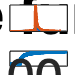

set(gcf,'position',[x0,y0,width,height])
box(gca,'on');
set(gca,'FontSize',20);
ylabel('DCT Magnitude')


%Plot overlay of phase functions to show general trend clearly
j=[31:60]

j =     31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60


ax2=subplot(2,1,2)

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


plot(X(:,j),Yphase(:,j),'lineWidth',1.2)
title('Evolution of phase function')
linkaxes([ax1,ax2,ax3],'x');

x0=10;
y0=10;
width=1150;
height=700

height = 700

set(gcf,'position',[x0,y0,width,height])
% ylim(axes1,[-17.4191352493244 19.6795712708698]);
box(gca,'on');
% Set the remaining axes properties
set(gca,'FontSize',20);
% Create legend
%legend(gca,'show');
xlim([120 180])
xlabel('Frequency (Hz)')
ylabel('Instantaneous Phase')

### 1.6 Interpolation of amplitude function

Interpolation can be used to create amplitude functions for intermediate velocities

%Choose samples to interpolate between and use these to create one long list of coordinates lxy (Loudness,X,Yamp)
Xcrop=[]


Xcrop =

     []



Y=[]


Y =

     []



L=[]


L =

     []



LXY=[]


LXY =

     []



k=[1 9 16 25 32]

k =      1     9    16    25    32


for j=1:5
    i=k(j)
    Xcrop(:,j)=X(:,i);
    Y(:,j)=Yamp(:,i);
    L=ones(length(X),1).*Loudness(i);
    LXY(:,:,j)=[L,Xcrop(:,j),Y(:,j)];
end

i = 1

i = 9

i = 16

i = 25

i = 32


C = permute(LXY,[1 3 2]);
C = reshape(C,[],size(LXY,2),1);
lxy=C

lxy =   -53.4138   75.6875    0.0039
  -53.4138   75.7500    0.0038
  -53.4138   75.8125    0.0038
  -53.4138   75.8750    0.0038
  -53.4138   75.9375    0.0038
  -53.4138   76.0000    0.0038
  -53.4138   76.0625    0.0038
  -53.4138   76.1250    0.0038
  -53.4138   76.1875    0.0038
  -53.4138   76.2500    0.0038



% Separate into vectors
l = lxy(:,1) ;
x = lxy(:,2) ;
y = lxy(:,3) ;

% use the function 'griddata'
[LI,XI] = meshgrid([round(l(1)):round(l(end))], x(1:length(X)) ) ;  
YI = griddata(l,x,y,LI,XI) ;

%Plot 2D
plot(XI,YI,':k','LineWidth',1.2)
title('Interpolation to create intemediate amplitude functions')
hold on
p1=plot(Xcrop,Y,'LineWidth',1.5)

p1 =   5×1 Line array:

  Line
  Line
  Line
  Line
  Line


legend([p1],{'1','13','33','55','71'})
xlim([125 140])
x0=10;
y0=10;
width=1150;
height=700

height = 700

set(gcf,'position',[x0,y0,width,height])
box(gca,'on');
% Set the remaining axes properties
set(gca,'FontSize',20);
% Create legend
legend(gca,'show');
xlabel('Frequency (Hz)')
ylabel('DCT Magnitude')

### 1.7 Interpolation of phase function

Interpolation can be used to create phase functions for intermediate velocities

%Choose samples to interpolate between and use these to create one long list of coordinates lxy (Loudness,X,Yphase)
Xcrop=[]


Xcrop =

     []



Y=[]


Y =

     []



L=[]


L =

     []



LXY=[]


LXY =

     []



J=[19 29 39 49 59]

J =     19    29    39    49    59


for j=1:5
    i=J(j);
    Xcrop(:,j)=X(:,i);
    Y(:,j)=Yphase(:,i);
    L=ones(length(X),1).*Loudness(i);
    LXY(:,:,j)=[L,X(:,j),Y(:,j)];
end

C = permute(LXY,[1 3 2]);
C = reshape(C,[],size(LXY,2),1);
lxy=C

lxy =   -35.7175   75.6875   -1.9328
  -35.7175   75.7500   -1.9288
  -35.7175   75.8125   -1.9250
  -35.7175   75.8750   -1.9211
  -35.7175   75.9375   -1.9180
  -35.7175   76.0000   -1.9165
  -35.7175   76.0625   -1.9159
  -35.7175   76.1250   -1.9148
  -35.7175   76.1875   -1.9116
  -35.7175   76.2500   -1.9065



% First separate 
l = lxy(:,1) ;
x = lxy(:,2) ;
y = lxy(:,3) ;

% use the function 'griddata'
[LI,XI] = meshgrid([round(l(1)):round(l(end))], x(1:length(X)) ) ; 
YI = griddata(l,x,y,LI,XI) ;

%Plot 2D
p2=plot(XI,YI,':k','LineWidth',1.2)

p2 =   17×1 Line array:

  Line    (data1)
  Line    (data2)
  Line    (data3)
  Line    (data4)
  Line    (data5)
  Line    (data6)
  Line    (data7)
  Line    (data8)
  Line    (data9)
  Line    (data10)
  Line    (data11)
  Line    (data12)
  Line    (data13)
  Line    (data14)
  Line    (data15)
  Line    (data16)
  Line    (data17)


title('Interpolation to create intemediate phase functions')
hold on
p1=plot(Xcrop,Y,'LineWidth',1.5)

p1 =   5×1 Line array:

  Line    (data18)
  Line    (data19)
  Line    (data20)
  Line    (data21)
  Line    (data22)


legend([p1],{'40','64','84','102','120'})
xlim([125 175])
x0=10;
y0=10;
width=1150;
height=700

height = 700

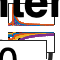

set(gcf,'position',[x0,y0,width,height])
box(gca,'on');
% Set the remaining axes properties
set(gca,'FontSize',20);
% Create legend
legend(gca,'show');
xlabel('Frequency (Hz)')
ylabel('Phase')